# **Dylan Thornburg ECEN 133 HW 6**

## 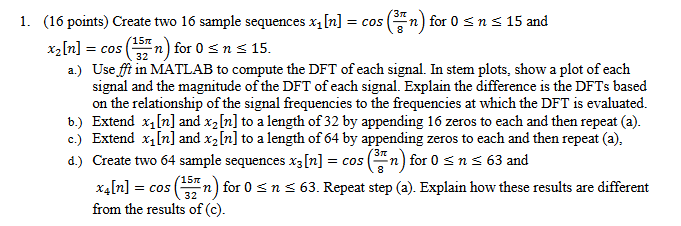

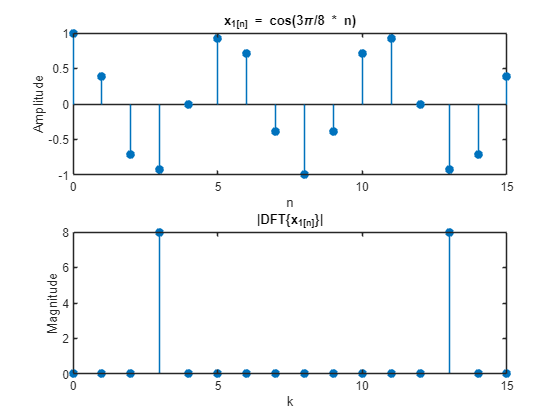

n = 0:15;

x1 = cos((3*pi/8) * n);

x2 = cos((15*pi/32) * n);

X1 = fft(x1);
X2 = fft(x2);

figure;
subplot(2,1,1);
stem(n, x1, 'filled');
title('x_1[n] = cos(3\pi/8 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:15, abs(X1), 'filled');
title('|DFT\{x_1[n]\}|');
xlabel('k'); ylabel('Magnitude');

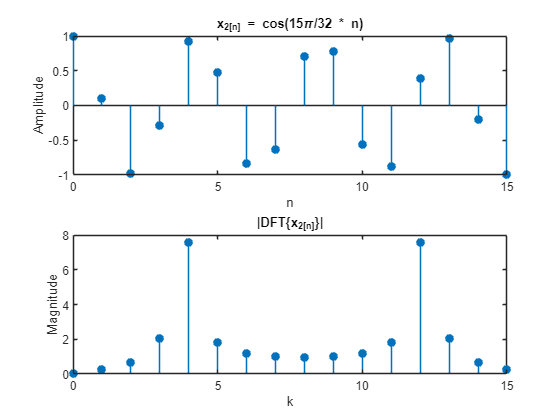

figure;
subplot(2,1,1);
stem(n, x2, 'filled');
title('x_2[n] = cos(15\pi/32 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:15, abs(X2), 'filled');
title('|DFT\{x_2[n]\}|');
xlabel('k'); ylabel('Magnitude');

wk = 2pi/N * k for k=0,1,...,N-1 and since N = 16, wk = 0, pi/8, 2pi/8,...,15pi/8. 

3pi/8 falls perfectly on one of these bins but 15pi/32 does not which is why we see spectral leakage.

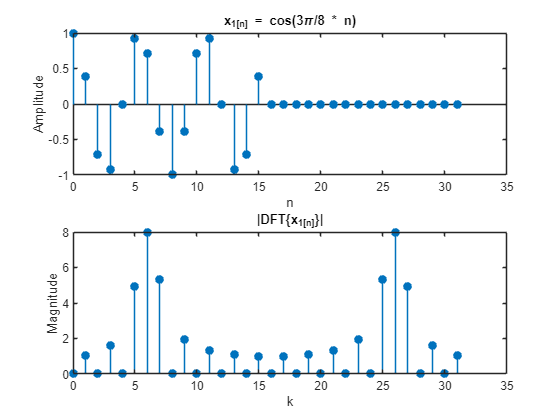

n = 0:15;
x1 = cos((3*pi/8) * n);

x2 = cos((15*pi/32) * n);

x1 = [x1, zeros(1,16)];

x2 = [x2, zeros(1,16)];

X1 = fft(x1);
X2 = fft(x2);

n = 0:31;
figure;
subplot(2,1,1);
stem(n, x1, 'filled');
title('x_1[n] = cos(3\pi/8 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:31, abs(X1), 'filled');
title('|DFT\{x_1[n]\}|');
xlabel('k'); ylabel('Magnitude');

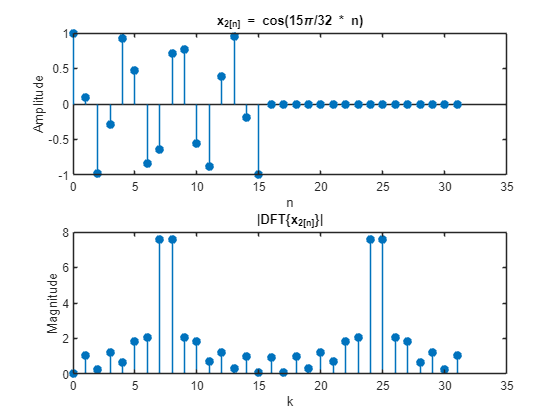

figure;
subplot(2,1,1);
stem(n, x2, 'filled');
title('x_2[n] = cos(15\pi/32 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:31, abs(X2), 'filled');
title('|DFT\{x_2[n]\}|');
xlabel('k'); ylabel('Magnitude');

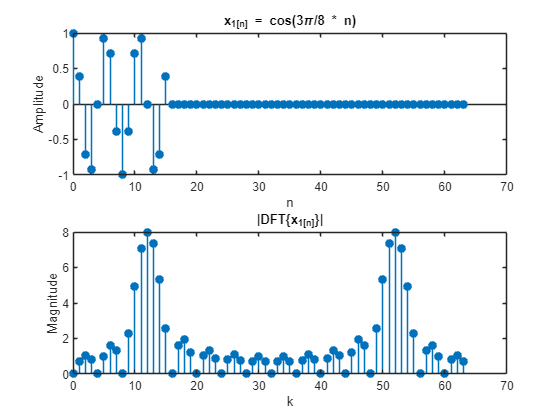

n = 0:15;
x1 = cos((3*pi/8) * n);

x2 = cos((15*pi/32) * n);

x1 = [x1, zeros(1,48)];

x2 = [x2, zeros(1,48)];

X1 = fft(x1);
X2 = fft(x2);

n = 0:63;

figure;
subplot(2,1,1);
stem(n, x1, 'filled');
title('x_1[n] = cos(3\pi/8 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:63, abs(X1), 'filled');
title('|DFT\{x_1[n]\}|');
xlabel('k'); ylabel('Magnitude');

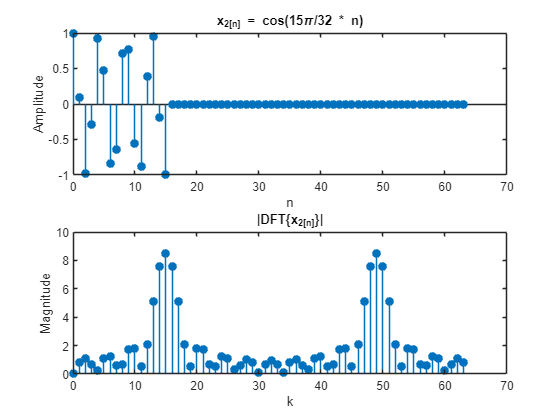


figure;
subplot(2,1,1);
stem(n, x2, 'filled');
title('x_2[n] = cos(15\pi/32 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:63, abs(X2), 'filled');
title('|DFT\{x_2[n]\}|');
xlabel('k'); ylabel('Magnitude');

For b and c, as we increase the zero padding, the cosine frequency gets visualized better.

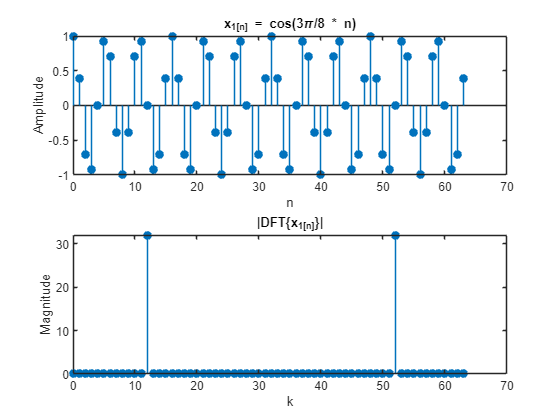

n = 0:63;
x1 = cos((3*pi/8) * n);

x2 = cos((15*pi/32) * n);

X1 = fft(x1);
X2 = fft(x2);

figure;
subplot(2,1,1);
stem(n, x1, 'filled');
title('x_1[n] = cos(3\pi/8 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:63, abs(X1), 'filled');
title('|DFT\{x_1[n]\}|');
xlabel('k'); ylabel('Magnitude');

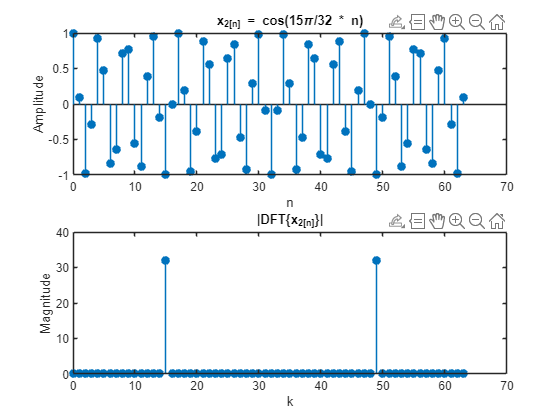


figure;
subplot(2,1,1);
stem(n, x2, 'filled');
title('x_2[n] = cos(15\pi/32 * n)');
xlabel('n'); ylabel('Amplitude');

subplot(2,1,2);
stem(0:63, abs(X2), 'filled');
title('|DFT\{x_2[n]\}|');
xlabel('k'); ylabel('Magnitude');

With an actual sampling increase, we now see 15pi/32 fall on a DFT bin, which is expected (15th bin and 64-15 bin). This is different from c as we now actually sample the whole cosine over 64 samples instead of windowing it.

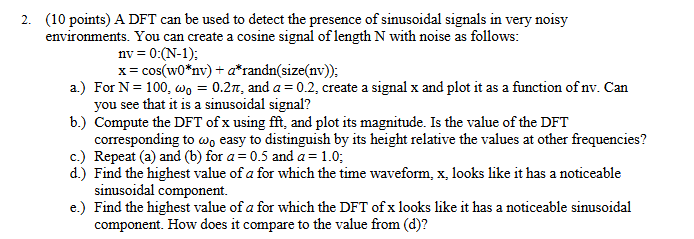

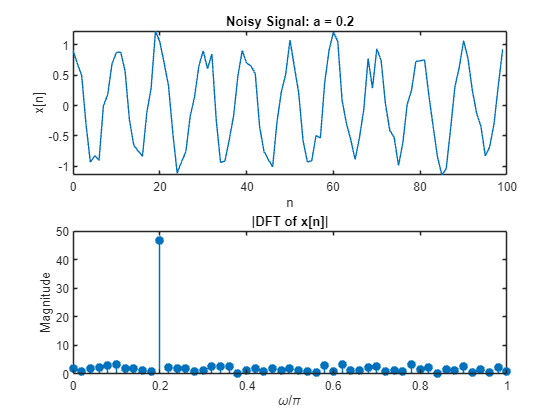

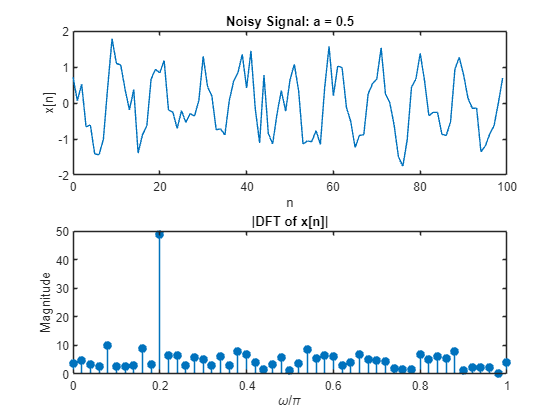

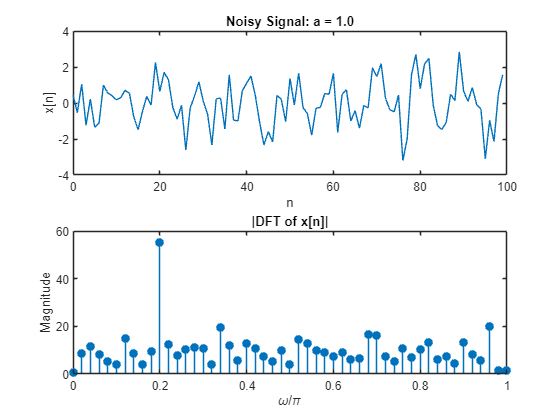

a= [.2, .5, 1];
N=100;
w0=.2*pi;
nv = 0:(N-1);
for i = 1:length(a)
    x = cos(w0*nv) + a(i)*randn(size(nv));
    figure;
    subplot(2,1,1);
    plot(nv, x);
    title(sprintf('Noisy Signal: a = %.1f', a(i)));
    xlabel('n'); ylabel('x[n]');
    
    X = fft(x);
    f=nv*2/N;
    subplot(2,1,2);
    stem(f, abs(X), 'filled');
    title('|DFT of x[n]|');
    xlabel('\omega/\pi'); ylabel('Magnitude');
    xlim([0, 1]);
end

**a**=.2 and .5 looks pretty sinusoidal. **a** = 1 doesn't as much. **a** = .7 looked like the highest **a** could be before the signal no longer appears sinusoidal. At around **a** = 2.5 depending on the random noise, the DFT no longer looks sinusoidal.

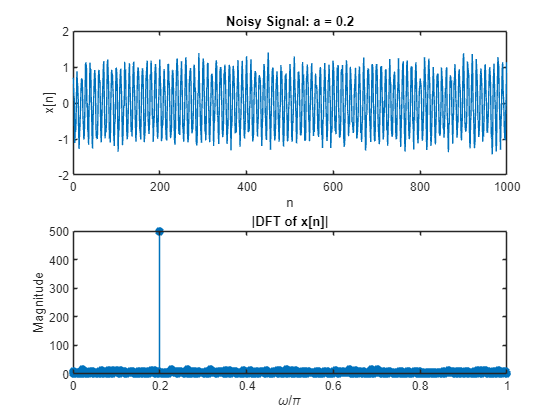

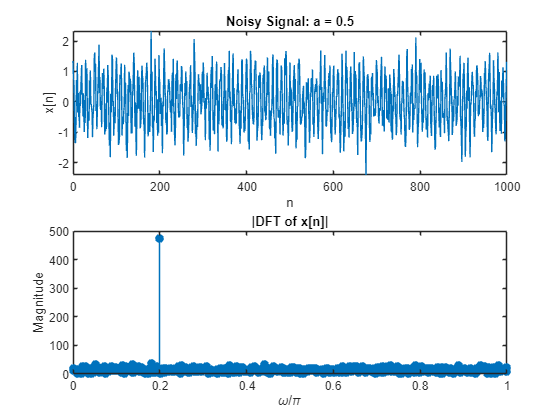

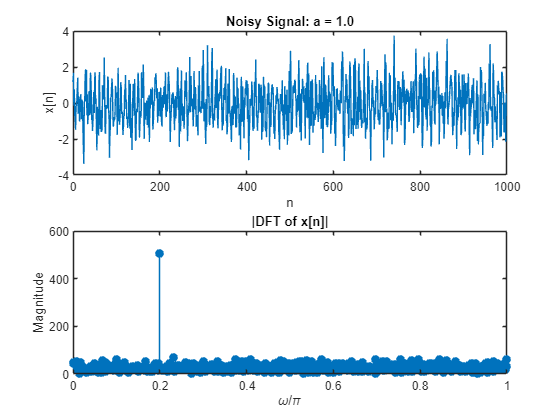

a= [.2, .5, 1];
N=1000;
w0=.2*pi;
nv = 0:(N-1);
for i = 1:length(a)
    x = cos(w0*nv) + a(i)*randn(size(nv));
    figure;
    subplot(2,1,1);
    plot(nv, x);
    title(sprintf('Noisy Signal: a = %.1f', a(i)));
    xlabel('n'); ylabel('x[n]');
    
    X = fft(x);
    f=nv*2/N;
    subplot(2,1,2);
    stem(f, abs(X), 'filled');
    title('|DFT of x[n]|');
    xlabel('\omega/\pi'); ylabel('Magnitude');
    xlim([0, 1]);
end

x(n) doesn't look like a sin at any of these **a**'s. When **a** is like .05, then it does a bit. For the DFT, **a** can be much higher such as 15 before abs(X) stops looking like the DFT of a sin wave. Overall the sin waves themselves don't look as clear, but the DFTs look way cleaner.

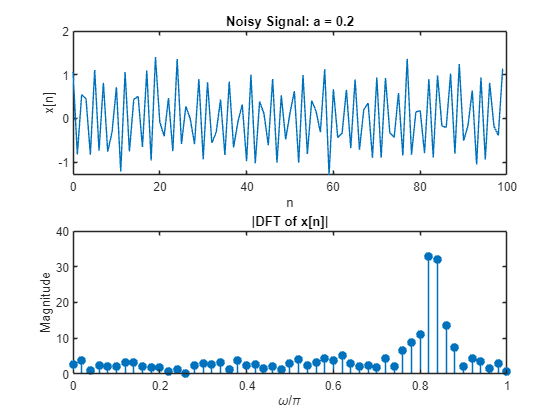

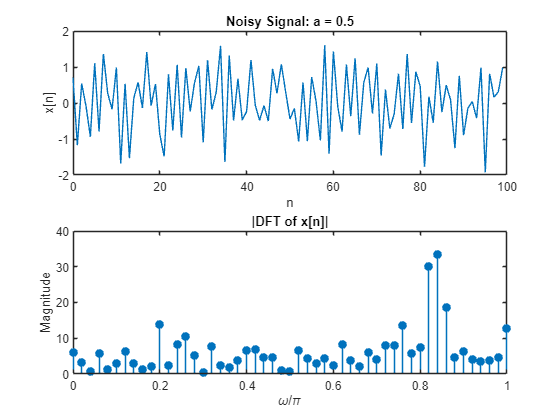

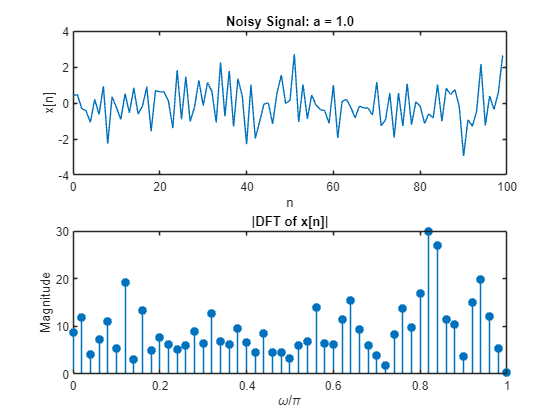

a= [.2, .5, 1];
N=100;
w0=.83*pi;
nv = 0:(N-1);
for i = 1:length(a)
    x = cos(w0*nv) + a(i)*randn(size(nv));
    figure;
    subplot(2,1,1);
    plot(nv, x);
    title(sprintf('Noisy Signal: a = %.1f', a(i)));
    xlabel('n'); ylabel('x[n]');
    
    X = fft(x);
    f=nv*2/N;
    subplot(2,1,2);
    stem(f, abs(X), 'filled');
    title('|DFT of x[n]|');
    xlabel('\omega/\pi'); ylabel('Magnitude');
    xlim([0, 1]);
end

The noise makes the signal not look sinusoidal around **a**=.7 again. Because there's spectral leakage even with no noise, the DFT of the sin wave isn't super clear. However, again around **a**=1.5, the DFT breaks down completely. 

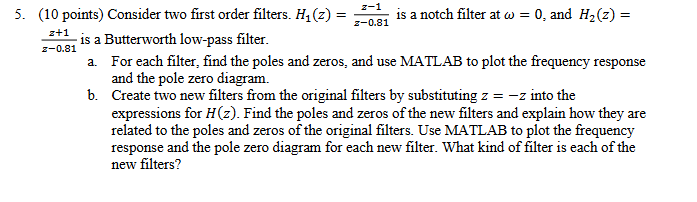

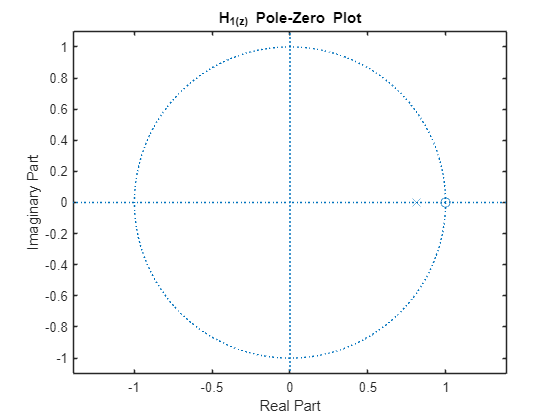

%H1(z) = (z-1)/(z-.81)
b1 = [1, -1];
a1 = [1, -.81];

%H2(z) = (z+1)/(z-.81)
b2 = [1, 1];
a2 = [1, -.81];

figure;
zplane(b1, a1);
title('H_1(z) Pole-Zero Plot');

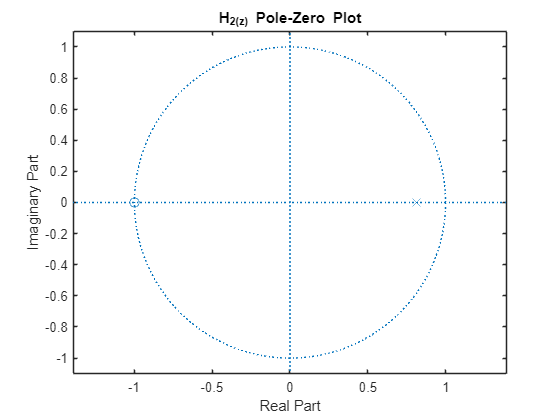


figure;
zplane(b2, a2);
title('H_2(z) Pole-Zero Plot');

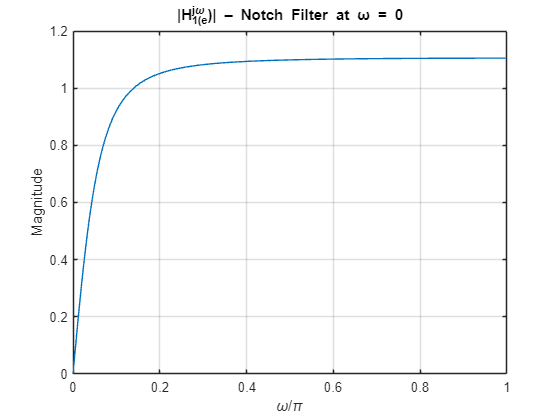


[H1, w] = freqz(b1, a1, 512);
[H2, w] = freqz(b2, a2, 512);

figure;
plot(w/pi, abs(H1)); grid on;
title('|H_1(e^{j\omega})| – Notch Filter at ω = 0');
xlabel('\omega/\pi'); ylabel('Magnitude');

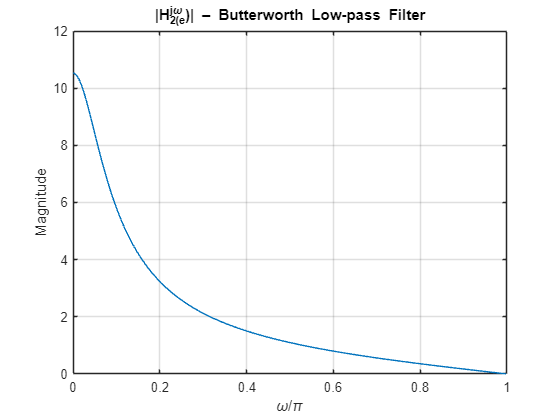

figure;
plot(w/pi, abs(H2)); grid on;
title('|H_2(e^{j\omega})| – Butterworth Low-pass Filter');
xlabel('\omega/\pi'); ylabel('Magnitude');

a. H1 zero at z=1 and pole at z =.81 | H2 zero at z=-1 and pole at z = .81

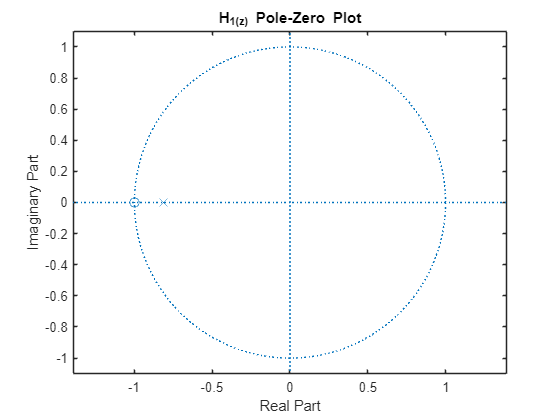

%H1(z) = (-z-1)/(-z-.81)
b1 = [-1, -1];
a1 = [-1, -.81];

%H2(z) = (-z+1)/(-z-.81)
b2 = [-1, 1];
a2 = [-1, -.81];

figure;
zplane(b1, a1);
title('H_1(z) Pole-Zero Plot');

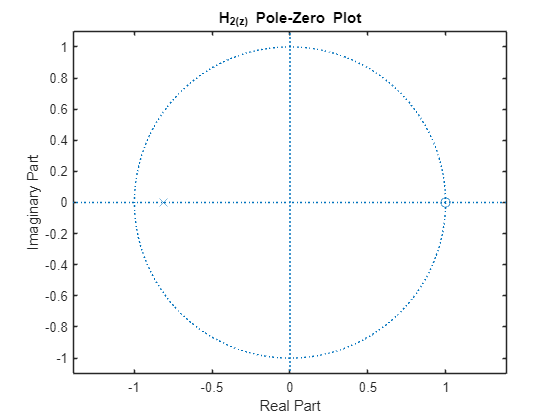


figure;
zplane(b2, a2);
title('H_2(z) Pole-Zero Plot');

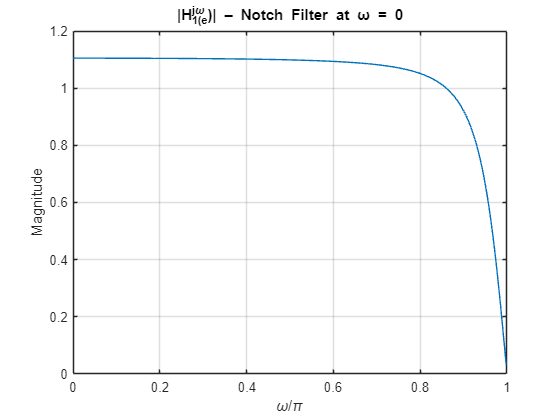


[H1, w] = freqz(b1, a1, 512);
[H2, w] = freqz(b2, a2, 512);

figure;
plot(w/pi, abs(H1)); grid on;
title('|H_1(e^{j\omega})| – Notch Filter at ω = 0');
xlabel('\omega/\pi'); ylabel('Magnitude');

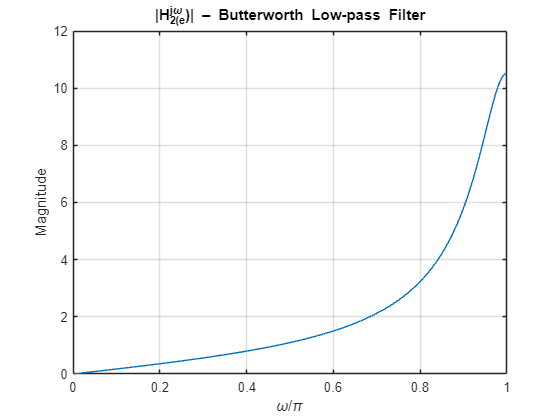

figure;
plot(w/pi, abs(H2)); grid on;
title('|H_2(e^{j\omega})| – Butterworth Low-pass Filter');
xlabel('\omega/\pi'); ylabel('Magnitude');

Putting z=-z inverted the filters. We now have a Butterworth High-Pass and Notch low pass. The zeros and poles get inverted too.

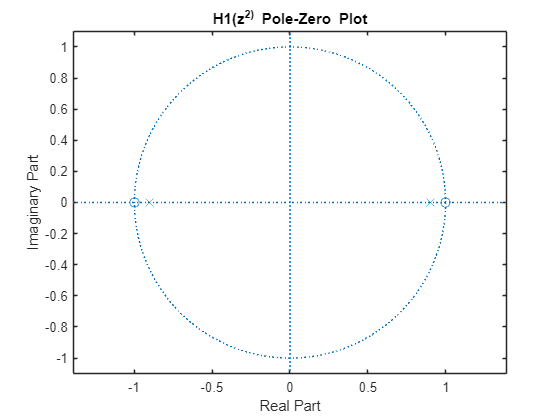

b11 = [1, 0, -1];
a11 = [1, 0, -.81];

b21 = [1, 0, 1];
a21 = [1, 0, -.81];

b12 = [-1, 0, -1];
a12 = [-1, 0, -.81];

b22 = [-1, 0, 1];
a22 = [-1, 0, -.81];

b31 = [1, 0, 0, -1];
a31 = [1, 0, 0, -.81];

b32 = [1, 0, 0, 1];
a32 = [1, 0, 0, -.81];


figure;
zplane(b11, a11);
title('H1(z^2) Pole-Zero Plot');

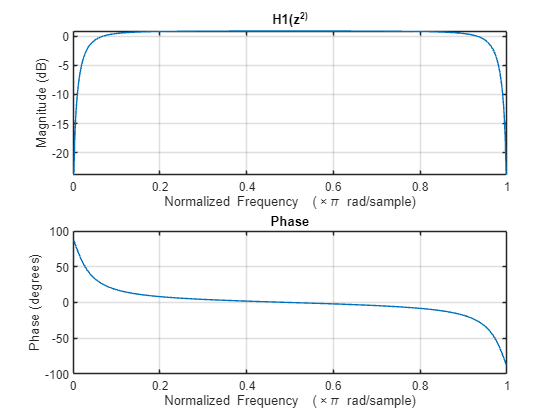

figure;
freqz(b11, a11, 512); 
title('H1(z^2)');

band pass^^^

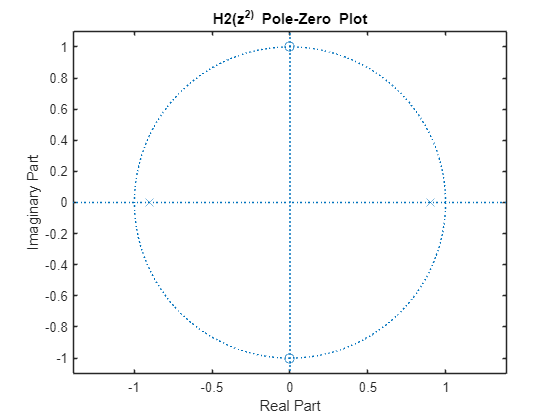


figure;
zplane(b21, a21);
title('H2(z^2) Pole-Zero Plot');

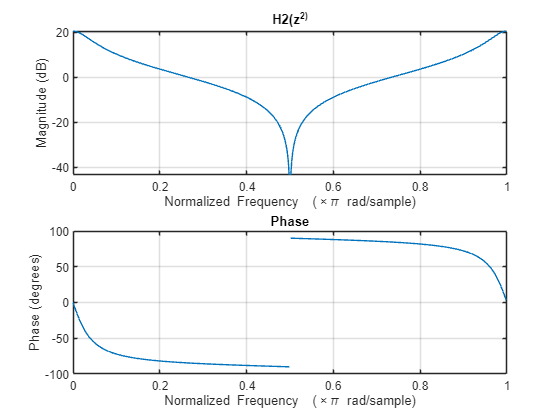

figure;
freqz(b21, a21, 512); 
title('H2(z^2)');

band stop^^^

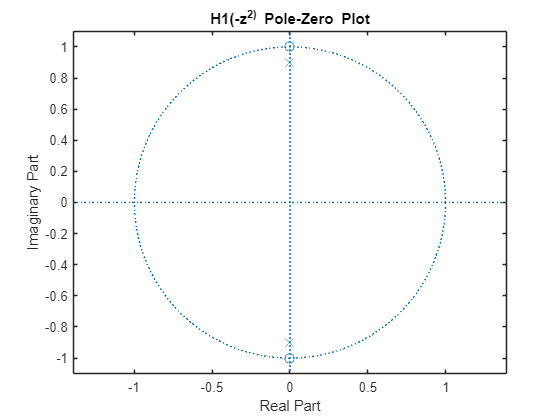


figure;
zplane(b12, a12);
title('H1(-z^2) Pole-Zero Plot');

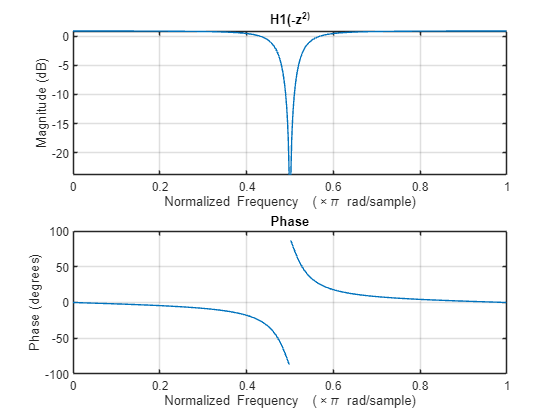

figure;
freqz(b12, a12, 512); 
title('H1(-z^2)');

notch^^^

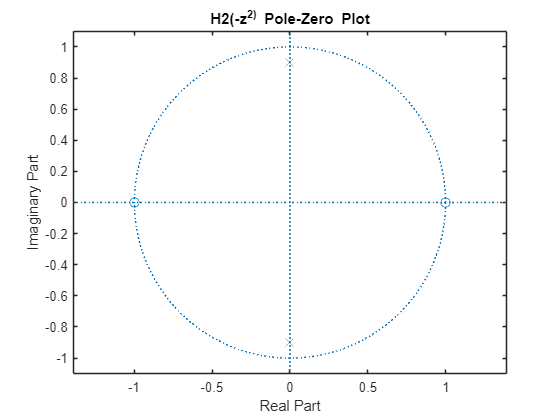


figure;
zplane(b22, a22);
title('H2(-z^2) Pole-Zero Plot');

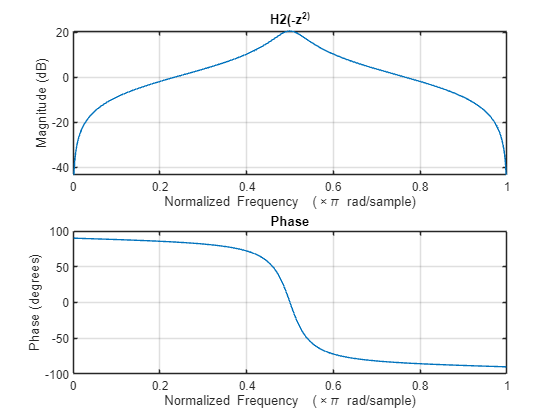

figure;
freqz(b22, a22, 512); 
title('H2(-z^2)');

band pass^^^?

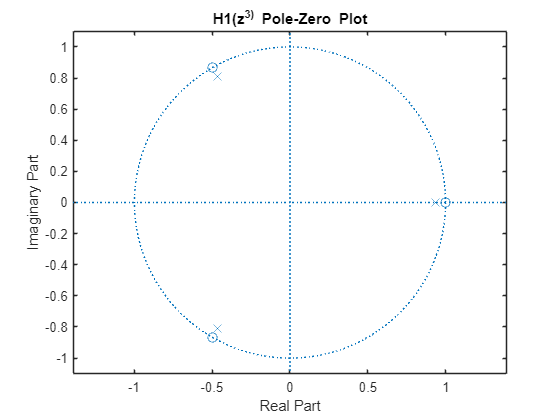


figure;
zplane(b31, a31);
title('H1(z^3) Pole-Zero Plot');

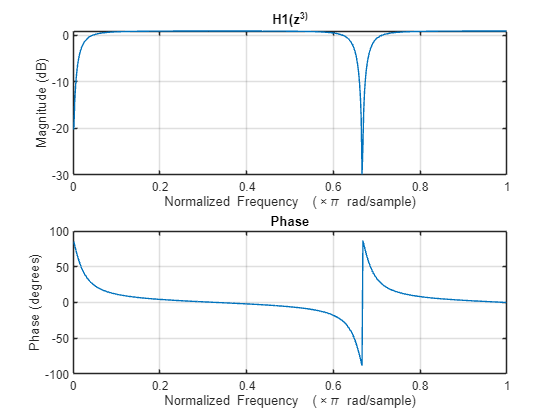

figure;
freqz(b31, a31, 512); 
title('H1(z^3)');

multiple notch^^^

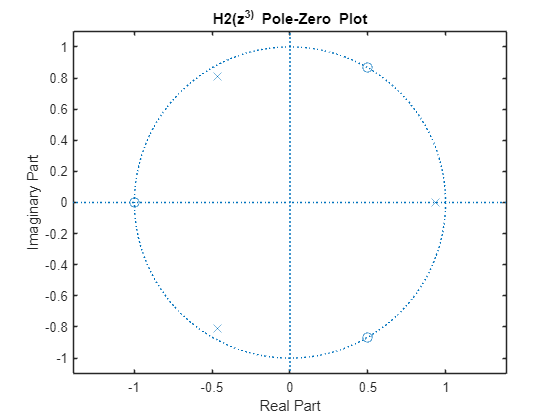


figure;
zplane(b32, a32);
title('H2(z^3) Pole-Zero Plot');

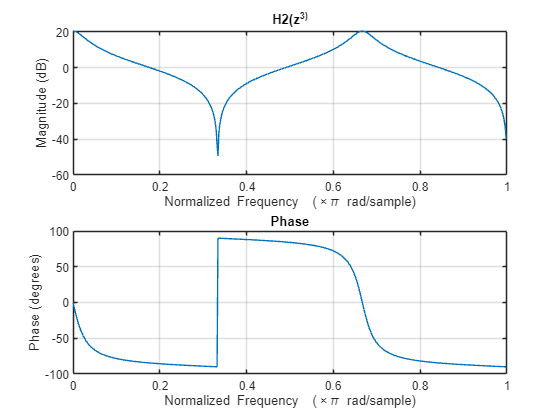

figure;
freqz(b32, a32, 512); 
title('H2(z^3)');

notch and band pass^^^

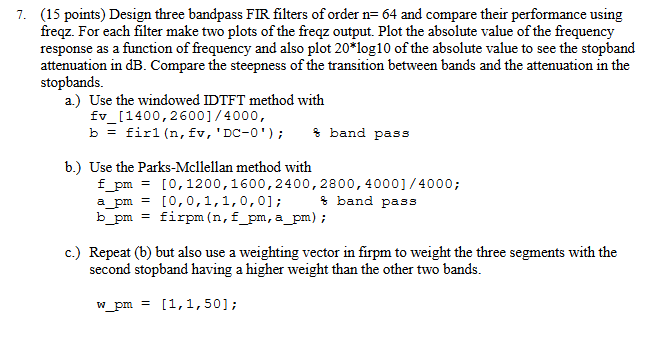

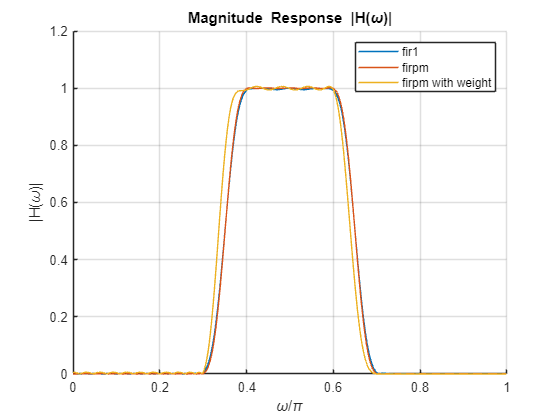

n=64;
fv = [1400, 2600]/4000;

b = fir1(n,fv,'DC-0');

f_pm = [0,1200,1600,2400,2800,4000]/4000;
a_pm = [0,0,1,1,0,0]; % band pass
b_pm = firpm(n, f_pm, a_pm);

w_pm = [1,1,50];
b_pm2 = firpm(n, f_pm, a_pm, w_pm);

%a=1 for fir filters
[Ha, w] = freqz(b, 1, 512);
[Hb, w] = freqz(b_pm, 1, 512);
[Hc, w] = freqz(b_pm2, 1, 512);

figure;
hold on;
plot(w/pi, abs(Ha)); 
plot(w/pi, abs(Hb));
plot(w/pi, abs(Hc));
legend('fir1', 'firpm', 'firpm with weight');
title('Magnitude Response |H(\omega)|');
xlabel('\omega/\pi'); 
ylabel('|H(\omega)|');
grid on;

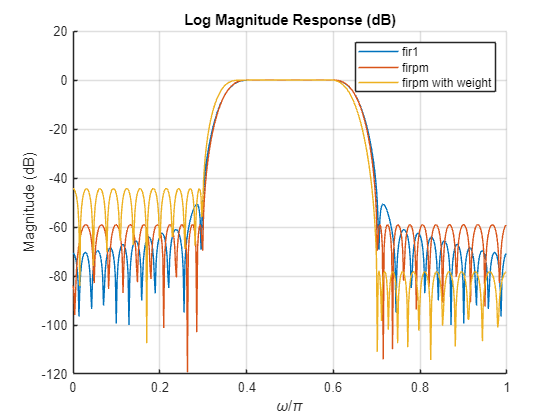


figure;
hold on;
%1e-6 to avoid log error
plot(w/pi, 20*log10(abs(Ha)+1e-6));
plot(w/pi, 20*log10(abs(Hb)+1e-6));
plot(w/pi, 20*log10(abs(Hc)+1e-6));
legend('fir1', 'firpm', 'firpm with weight');
title('Log Magnitude Response (dB)');
xlabel('\omega/\pi'); 
ylabel('Magnitude (dB)');
grid on;

firpm has the deepest attenuation on avg. All slopes are pretty similar, but firpm might be the steepest. fir1 has the least ripple in the bandpass gap. Overall, it appears firpm with no weight is the best filter.